Jesus Molina Roldan 

# Mètode del punt fix o Mètode de la iteració simple

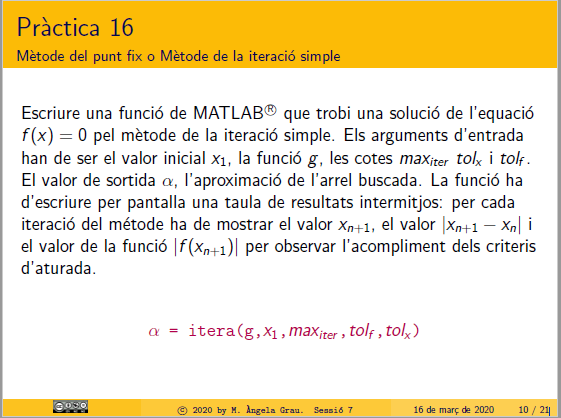  

format long G
g = @(x)cos(x); x1 = 1; maxiter = 15; tolf = 0.5*10^(-18); tolx = 0.5*10^(-18);
f = @(x)cos(x) -x;
dg = @(x)-sin(x);
alpha = itera(f, g, dg, x1, maxiter, tolf, tolx)

T1 = 15×4 table
    k            x_n                  tolf                   tolx        
    __    _________________    ___________________    ___________________

     0                    1                    Inf                    Inf
     1     0.54030230586814      0.317250909978254       0.45969769413186
     2    0.857553215846393      0.203263425348614      0.317250909978254
     3    0.654289790497779      0.139190568244786      0.203263425348614
     4    0.793480358742566     0.0921115851198091      0.139190568244786
     5    0.701368773622757     0.0625909092778977     0.0921115851198091
     6    0.763959682900654     0.0418572578739465     0.0625909092778977
     7    0.722102425026708     0.0283153367370528     0.0418572578739465
     8    0.750417761763761     0.0190137193412507     0.0283153367370528
     9     0.73140404242251     0

alpha =          0.740147335567876


alpha = fzero(f,x1)

alpha =          0.739085133215161


x0=0.5; 
f =@(x)x+log(x);
g=@(x)exp(-x); 
dg=@(x)-exp(-x);
tol=0.0005; nmax=15;
alpha = itera( f, g, dg, x0, nmax, tol, tol)

T1 = 11×4 table
    k            x_n                   tolf                    tolx        
    __    _________________    ____________________    ____________________

     0                  0.5                     Inf                     Inf
     1    0.606530659712633       0.106530659712633       0.106530659712633
     2    0.545239211892605      0.0612914478200284      0.0612914478200284
     3    0.579703094878068      0.0344638829854633      0.0344638829854632
     4    0.560064627938902      0.0196384669391663      0.0196384669391664
     5    0.571172148977215      0.0111075210383133      0.0111075210383133
     6    0.564862946980323     0.00630920199689167     0.00630920199689167
     7    0.568438047570066     0.00357510058974275     0.00357510058974275
     8    0.566409452746921     0.00202859482314555     0.00202859482314544
     9    0

alpha =          0.566907212935471


# Convergència "a priori"               

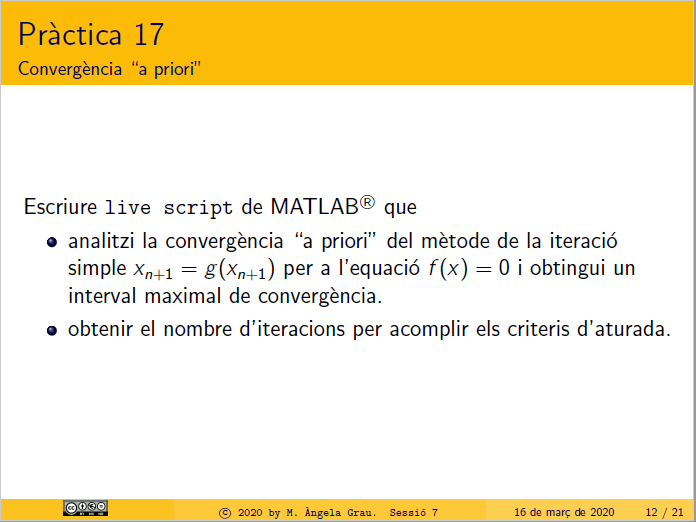

# Convergència "a priori"

t = 0.01:0.01:1;
f=@(x)x+log(x);
y=zeros(size(t));
subplot(221),plot(t,f(t),t,y),title('x+log(x)=0');
dg = @(x)-1./x;
subplot(222),convergencia_a_priori(dg,t);
dg=@(x)-exp(-x);
subplot(223),convergencia_a_priori(dg,t);
dg=@(x)(1-exp(-x))/2;
subplot(224),convergencia_a_priori(dg,t);

# Nombre d'iteracion 

**Obtenir el nombre d'iteracions per acomplir els criteris d'aturada**

x0=0.5; 
f =@(x)x+log(x);
g=@(x)exp(-x); 
dg=@(x)-exp(-x);
tol=eps; nmax=15;
alpha = itera( f, g, x0, Inf, eps, eps)

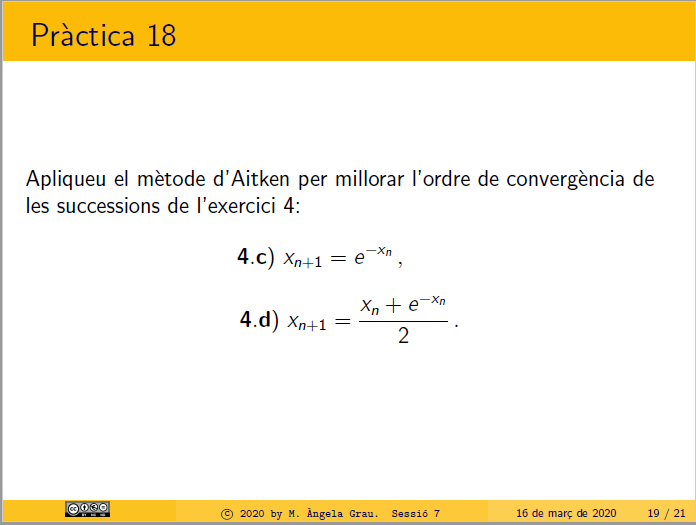

# Mètode d'Aitken

4c)

f =@(x)x+log(x);
g=@(x)exp(-x); 
dg=@(x)-exp(-x);
x0=0.5; tol = 0.000002;
maxiter = 9;
[A] = aitkenfixpt(f, g, dg, x0, maxiter, tol)

4d)

f =@(x)x+log(x);
g = @(x) ((x+exp(-x))/2);
dg = @(x) ((1-exp(-x))/2);
tol = 0.000002;
x0 = 0.5;
maxiter = 9;
[A] = aitkenfixpt(f, g, dg, x0, maxiter, tol)

# Mètode del punt fix o Mètode de la iteració simple

function [xn] = itera(f, g, dg, x1, maxiter, tolf, tolx)
    if abs(dg(x1))<1
        xnmas1 = x1;
        xn = x1;
        k = 0;
        R  = [k,x1,Inf,Inf];
        cotaf=Inf; 
        cotax=Inf;
        while(abs(cotaf) >tolf &&  abs(cotax) > tolx && k< maxiter)
            xn = xnmas1;
            xnmas1 = g(xnmas1);
            k = k+1;
            cotaf = abs(f(xnmas1));
            cotax = abs(xnmas1-xn);
            R  = [R ;k xnmas1 cotaf cotax];
        end
        R = R(1:(end-1),:);
        T1 = array2table(R,'VariableNames',{'k','x_n','tolf','tolx'})
    else 
        fprintf('\n Mètode divergent\n')
    end
end

# Convergència "a priori"

function convergencia_a_priori(dg,t)
    y=ones(size(t));
    plot(t,dg(t),t,y,'r',t,-y,'r');
    dgt = dg(t)
    %si -1<=dgt<= 1 convergente sino divergente
    dgt(dgt>1) = 2;
    dgt(dgt<-1) = 2;
    if ismember(2,dgt)
        title('Divergente')
    else
        title('Convergente')
    end
end

# mètode d'Aitken

function [A] = aitkenfixpt(f, g, dg, x0, maxiter, tol)
        A = [];
        if abs(dg(x0)) < 1
            %Metode d'Aitken
            i = 0;
            while (i < maxiter && abs(x0) > tol)
                x1 = g(x0);
                x2 = g(x1);
                aitkenX = (x2*x0-x1^2)/(x2-2*x1+x0);
                A = [A; aitkenX];
                x0 = aitkenX;
                i = i+1;
            end
        else
            fprintf('Mètode divergent\n')
        end
end